# AAP 05 - Medição do canal sem fio usando o CC1350

**Nomes:     **

- - André Felipe

- - Júlio Henrique 

- - Letícia Rodrigues

- - Luiz Felipe

## Tarefa 1 - Coeficiente de perca de percurso *n* e modelo log-distância 

1 - Para uma distância de separação entre TX e RX conhecida, faça a medição da RSSI de, pelo menos, 1000 pacotes

2 - Obtenha a média dos valores de RSSI medidos anteriormente

3 - Repita os passos anteriores para pelo menos 4 distâncias diferentes

4 - Obtenha o valor do coeficiente de perda de percurso n, e o modelo log-distância correspondente, de forma semelhante à realizada nos Exemplos 1 e 2;

5 - Faça um gráfico com os valores medidos e o modelo projetado, no estilo da Figura 2.

### Código:

Organização do console 

clc; 
clear; 
close all;
format shortEng

Carregamento dos Dados

addpath('Tarefa_1');

data_05m = load("Tarefa_1/dados_meio_m.mat"); 
data_1m = load("Tarefa_1/dados_1m.mat"); 
data_2m = load("Tarefa_1/dados_2m.mat"); 
data_3m = load("Tarefa_1/dados_3m.mat"); 
data_4m = load("Tarefa_1/dados_4m.mat"); 
data_5m = load("Tarefa_1/dados_5m.mat"); 

Cálculo das médias de RSSI 

Pr_d0 = mean(data_05m.dados_meio_m(:,3));  
RSSI_1m = mean(data_1m.dados_1m(:,3)); 
RSSI_2m = mean(data_2m.dados_2m(:,3)); 
RSSI_3m = mean(data_3m.dados_3m(:,3)); 
RSSI_4m = mean(data_4m.dados_4m(:,3)); 
RSSI_5m = mean(data_5m.dados_5m(:,3));  

Distância de referência

d0 = 0.5; 

Vetor de distâncias e sinal

RSSI = [ RSSI_1m, RSSI_2m, RSSI_3m, RSSI_4m, RSSI_5m ]; 
d = [1.0, 2.0, 3.0, 4.0, 5.0]; 

Tamanho do vetor

k = length(RSSI); 

Criação da variável símbolica N

syms n; 

Inicialização do erro quadrático (J) 

J = 0; 

Soma do erro quadrático entre as medidas teóricas e as estimativas 

for i = 1:k

    P = Pr_d0 - 10*n*log10(d(i)/d0) ;   % Potência média recebida em determinada distância D
    J = J + (RSSI(i) - P)^2 ;

end

Derivada de J em relação a n

dJ_dn = diff(J, n);

Resolução do valor de n 

n_meio = double(solve(dJ_dn == 0, n));
disp('O valor de n para o meio medido é: ')

O valor de n para o meio medido é: 


disp(n_meio)

     3.0206e+000



Potência média recebida de acordo com o modelo 

P_modelo = double(Pr_d0 - 10 * n_meio * log10(d / d0)); 

Plotagem do Gráfico 

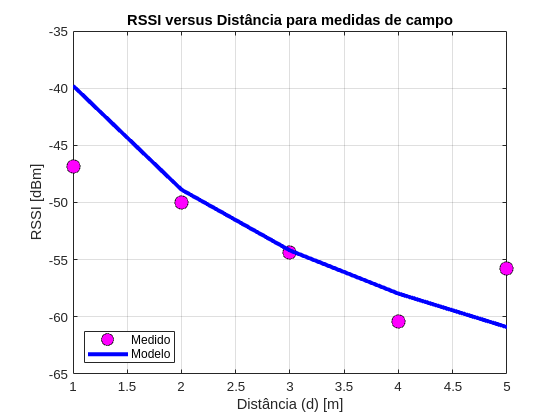


figure;
plot(d, RSSI, 'ko', 'MarkerFaceColor', 'm', 'MarkerSize', 10); % Dados medidos
hold on;
plot(d, P_modelo, 'b-', 'LineWidth', 3); % Modelo ajustado


% Configurações do gráfico
grid on;
xlabel('Distância (d) [m]');
ylabel('RSSI [dBm]');
title('RSSI versus Distância para medidas de campo');
legend('Medido', 'Modelo', 'Location', 'SouthWest');

### Conclusão: 

- Existem desvios entre as medidas e o modelo? 

- Isso significa que está errado? Por quê? 

- Esse coeficiente pode ser usado para outros ambientes? Por quê?

## Tarefa 2 - **Análise do Desvanecimento em Sinais RSSI Usando Distribuição Nakagami-m**

1- Realize a coleta de pelo menos 10000 (dez mil) amostras de RSSI, em um cenário com distância fixa e linha de visada entre TX e RX; 

2 - Repita o primeiro passo para um cenário diferente, sem linha de visada entre TX e RX; 

3 - Faça o ajuste da pdf do conjunto de amostras recebido de acordo com uma distribuição Nakagami-m, veja o Exemplo 3; 

4 - Compare sua pdf ajustada com o histograma de medidas, de forma semelhante à Figura 4. 

Observações:

 • Pode acontecer de valores impossíveis (maiores que 0 dBm ou menores que -120 dBm) aparecerem nas medições devido à erros na comunicação ou no processamento. Você pode remover os valores absurdos de forma a melhorar a visualização e o resultado.

 • Se durante a execução do experimento os erros de pacotes forem muito frequentes, isso significa que o enlace não está adequado. Neste caso, diminua a distância entre o TX e o RX e recomece o experimento.

### Código:

Organização do console 

clc; 
clear; 
close all;
format shortEng

Carregamento dos Dados

addpath('Tarefa_2');

load("dados_2m_CLV.mat")
load("dados_2m_SLV.mat")

Extrai os dados da terceira coluna (RSSI em dBm)

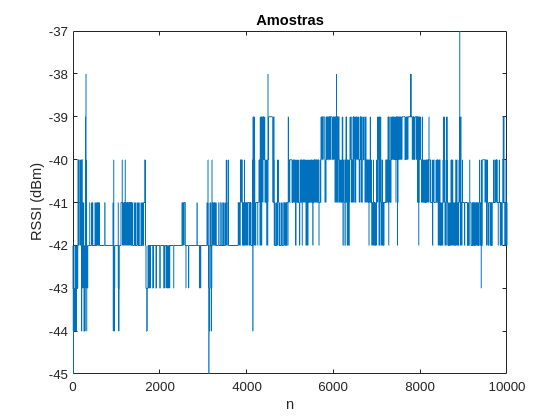

RSSIdBm_CLV = dados_2m_CLV(:, 3);
figure
plot(linspace(1, 10000, 10000), RSSIdBm_CLV);
title('Amostras');
xlabel('n');
ylabel('RSSI (dBm)');

Converte para mW

RSSI = 10.^(RSSIdBm_CLV/10); %mW

Média de RSSI

RSSI_barra = mean(RSSI); %mW

Calculo de h

h = sqrt(RSSI/RSSI_barra); 

Teste se $E^{h^2 } =1$

M_2 = mean(h.^2); 

Teste com p = 2, idealmente p >= 2

p = 2; 

Cálculo de m utlizando estimadores de momento generalizado  [5, eq.9]

m = mean(h.^(1/p)) / (2*p*( mean(h.^(1/p + 2)) - mean(h.^(1/p)) ))

m =     15.3585e+000


Plota o hitograma e pdf nakagami-m

h_values = linspace(0, max(h), 1000);
pdf_h = (2 * m^m * h_values.^(2*m - 1)) ./ (gamma(m)) .* exp(-m * h_values.^2)

pdf_h =      0.0000e+000    64.7490e-078    57.1358e-069     9.7665e-063    50.4007e-060    38.2093e-057     8.6104e-054   839.9838e-054    44.3992e-051     1.4696e-048    33.6252e-048   570.6763e-048     7.5679e-045    81.5822e-045   737.2029e-045     5.7218e-042    38.9004e-042   235.4136e-042     1.2851e-039     6.3992e-039    29.3410e-039   124.8781e-039   496.7830e-039     1.8583e-036     6.5709e-036    22.0632e-036    70.6339e-036   216.3811e-036   636.3226e-036     1.8015e-033     4.9226e-033    13.0131e-033    33.3499e-033    83.0170e-033   201.0714e-033   474.6042e-033     1.0933e-030     2.4612e-030     5.4213e-030    11.6972e-030    24.7478e-030    51.3915e-030   104.8415e-030   210.2927e-030   415.0499e-030   806.6323e-030     1.5447e-027     2.9166e-027     5.4329e-027     9.9898e-027


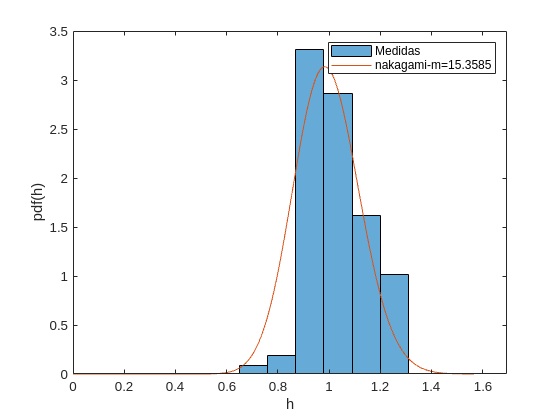

histogram(h, 10, 'Normalization', 'pdf');
hold on
plot(h_values, pdf_h);
legend('Medidas', ['nakagami-m=' num2str(m)])
xlabel('h');
ylabel('pdf(h)')
hold off

### Conclusão

- Quando cada tipo de distribuição de desvanecimento melhor se aplica para descrever um cenário real? 

- Por que é importante conhecer o modelo do desvanecimento em um enlace de comunicação sem fio?